Usando los datos de censo de población de estados unidos de 1790 a 1990.

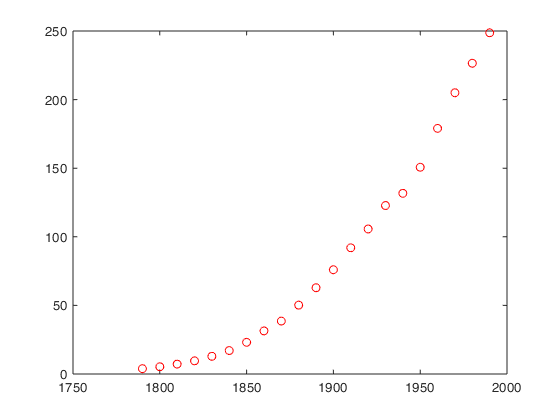

load census
plot(cdate,pop,'ro')

[p error]=polyfit(cdate,pop,2)

p = 	1.0e+04 *

    0.0000   -0.0024    2.1130


error = struct with fields:
        R: [3×3 double]
       df: 18
    normr: 12.6107


ajuste=polyval(p,cdate,error)

ajuste =     5.5830
    5.3121
    6.3495
    8.6951
   12.3489
   17.3109
   23.5811
   31.1596
   40.0463
   50.2413


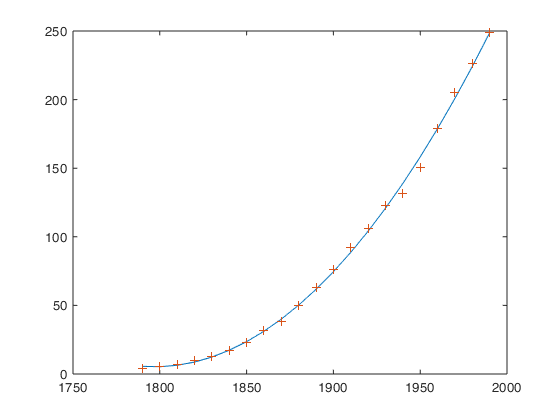

plot(cdate,ajuste,'-',cdate,pop,'+')

dif=pop-ajuste

dif =    -1.6830
   -0.0121
    0.8505
    0.9049
    0.5511
   -0.2109
   -0.4811
    0.2404
   -1.4463
   -0.0413


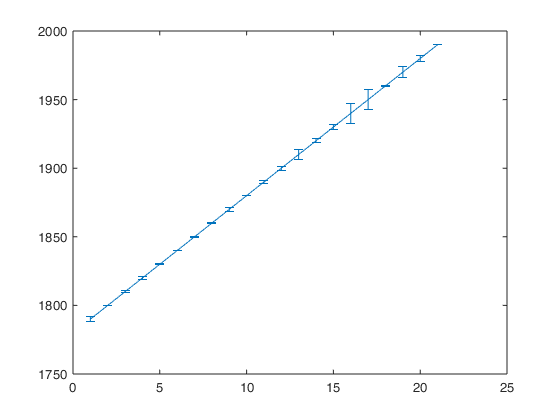

errorbar(cdate,dif)

[ajuste delta]=polyval(p,cdate,error)

ajuste =     5.5830
    5.3121
    6.3495
    8.6951
   12.3489
   17.3109
   23.5811
   31.1596
   40.0463
   50.2413


delta =     3.4616
    3.3105
    3.2069
    3.1429
    3.1095
    3.0978
    3.0996
    3.1081
    3.1180
    3.1254


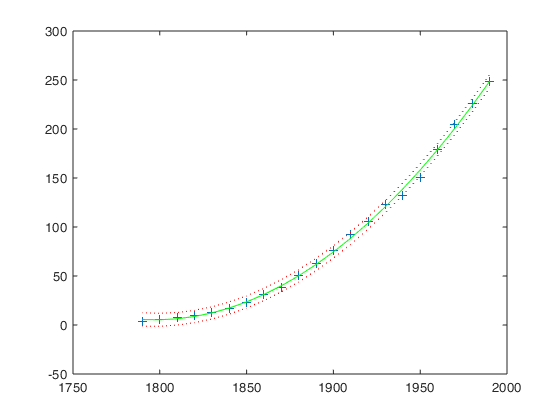

plot(cdate,pop,'+',...
    cdate,ajuste,'g-',...
    cdate,ajuste+2*delta,'r:',...
    cdate,ajuste-2*delta,'r:')